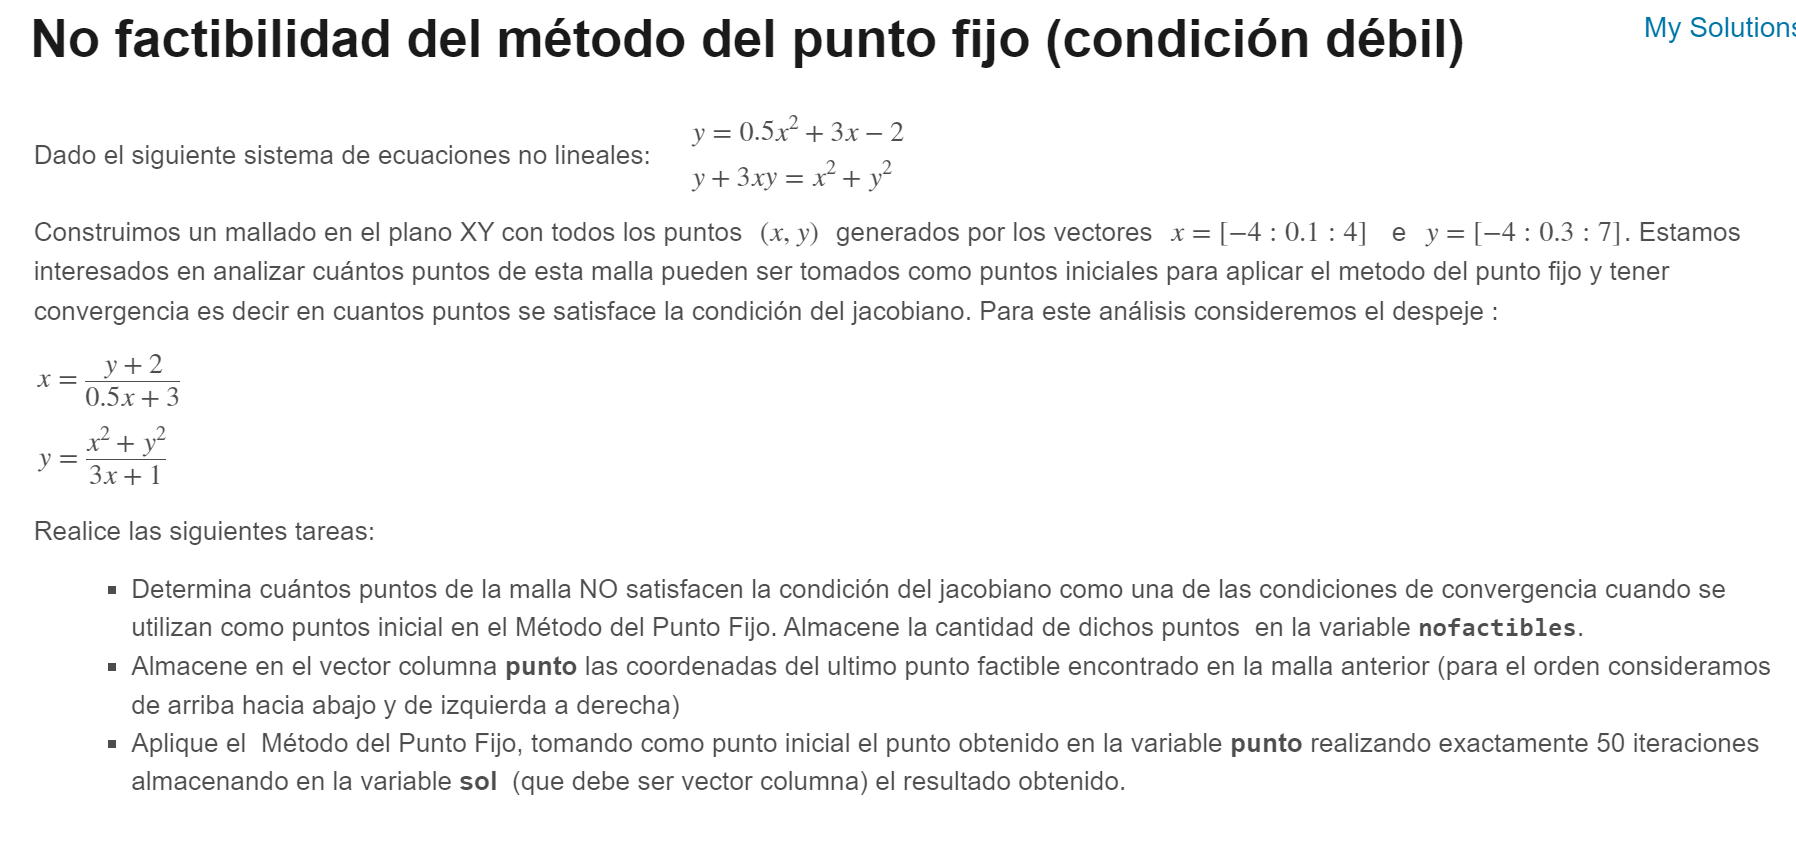

format long

syms x y
u = (y + 2)/(0.5*x + 3);
v = (x^2 + y^2)/(3*x + 1);
G = [u;v];
G = matlabFunction(G);

dG = jacobian(G(x,y),[x,y]);
dG_func = matlabFunction(dG);

nofactibles = 0;
for xi = -4:0.1:4
    for yi = -4:0.3:7
        M = double(dG_func(xi,yi));
        if norm(M,inf) > 1
            punto = [xi ; yi];
            nofactibles = nofactibles + 1;
        end
    end
end

function x1 = pfijos(g,x0,MaxIter)
    error = 1;
    for i = 1:MaxIter
        x1 = g(x0(1),x0(2));
        error = norm(x1-x0,inf)/norm(x1,inf);
        x0 = x1;
    end
end

punto

punto =    4.000000000000000
   6.799999999999999


nofactibles

nofactibles =         1967



sol = pfijos(G,punto,50)

sol =    0.646903820558726
   0.149953738202916




normasol = norm(sol,inf)

normasol =    0.646903820558726
